# 运用Logistic Regression对iris数据进行分类


clear
clc

# 读入iris数据，并可视化

load iris_dataset.mat

iris数据包含三类，每类50个样本共150个，每个样本的维数是4。用PCA降到2维进行可视化。iris数据的第一类与其它两类分的比较开，第二类和第三类有重叠。

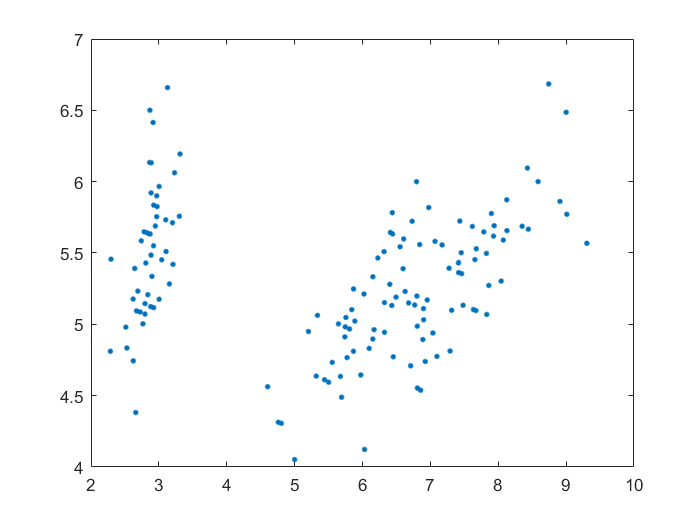

[Trans,~] = pca(irisInputs');
iris_dr = Trans'*irisInputs;
figure;
plot(iris_dr(1,:),iris_dr(2,:),'.','MarkerSize',10);

# 构造训练样本和测试样本

本次实验训练样本和测试样本相同，为iris数据的前两类，并只选用样本的前2维进行实验。

X = irisInputs(1:2,1:100);
X = [X;ones(1,100)];
Y = [ones(50,1);zeros(50,1)];

# 梯度下降法求解Logistic Regression

W初始化为最小二乘解 $X^+ Y$或[1,1,1]，也可以随机初始化。这里是通过给X补1，来代替b的求导更新。

此处没有给出停止的条件，简单迭代1000次。学习率的选取用了[Backtracking line search](https://en.wikipedia.org/wiki/Backtracking_line_search)

% W = pinv(X')*Y;
W = [1,1,1]';
for i = 1 : 1000
    alphak = btl_search(@my_fun,@my_grad,W,X,Y,0.1,0.5);
    alp(i) = alphak;
    W = W - alphak * my_grad(W,X,Y);
    f(i) = my_fun(W,X,Y);
end

# 画损失函数的收敛曲线

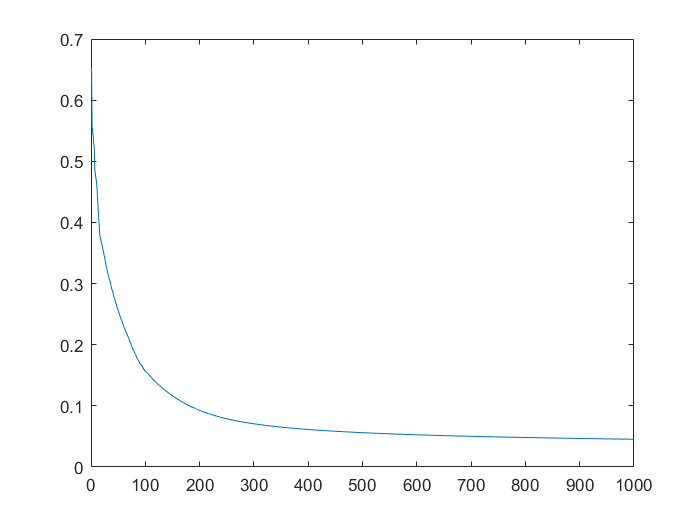

figure;
plot(f)


for i = 1 : 100
    y_test(i) = my_sig(W,X(:,i));
end


# 画属于第一类的后验概率杆状图

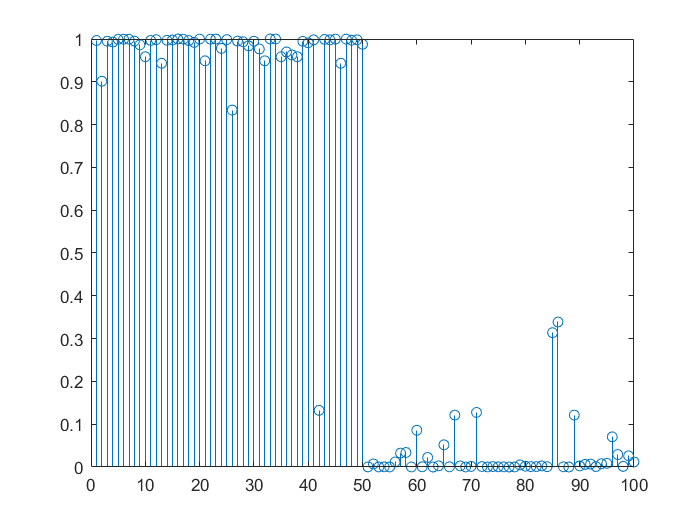

figure

stem(y_test)